## Exercise 2

close all   % Clearing figures
clc
clear
syms k x
f = eulergamma^(-k*x^2)     %a Defining f

$$f = \frac{1}{{\mathrm{eulergamma}}^{k\,x^{2}}}$$

g(x) = diff(f)          %b Let g(x) = f'

$$g(x) = -\frac{2\,k\,x\,\log\left(\mathrm{eulergamma}\right)}{{\mathrm{eulergamma}}^{k\,x^{2}}}$$

gnew = subs(g(x),k,4)     %c Substituting 4 for k     

$$gnew = -\frac{8\,x\,\log\left(\mathrm{eulergamma}\right)}{{\mathrm{eulergamma}}^{4\,x^{2}}}$$

fplot(gnew,[-2 2])       %d Plots g from x = [-2,2]
xlabel('x');        %x title
ylabel("f'");       %y title
title("f' vs x")        %graph title
hold on     %All plot commands go to same figure
h = diff(gnew)      %Finds deriv of g

$$h = \frac{64\,x^{2}\,{\log\left(\mathrm{eulergamma}\right)}^{2}}{{\mathrm{eulergamma}}^{4\,x^{2}}}-\frac{8\,\log\left(\mathrm{eulergamma}\right)}{{\mathrm{eulergamma}}^{4\,x^{2}}}$$

xstat = solve(h==0)     %e Finds stationary points of g by setting its deriv to 0

$$xstat = \left(\begin{array}{c} -\frac{\sqrt{\frac{1}{2\,\log\left(\mathrm{eulergamma}\right)}}}{2}\\ \frac{\sqrt{\frac{1}{2\,\log\left(\mathrm{eulergamma}\right)}}}{2} \end{array}\right)$$

gstat1 = subs(gnew,x,xstat(1))    %finds value of g at xstat1

$$gstat1 = \frac{4\,\log\left(\mathrm{eulergamma}\right)\,\sqrt{\frac{1}{2\,\log\left(\mathrm{eulergamma}\right)}}}{{\mathrm{eulergamma}}^{\frac{1}{2\,\log\left(\mathrm{eulergamma}\right)}}}$$

plot(xstat(1),gstat1,'or')        %f Plots xstat1, gstat1

gstat2 = subs(gnew,x,xstat(2))    %finds value of g at xstat2

$$gstat2 = -\frac{4\,\log\left(\mathrm{eulergamma}\right)\,\sqrt{\frac{1}{2\,\log\left(\mathrm{eulergamma}\right)}}}{{\mathrm{eulergamma}}^{\frac{1}{2\,\log\left(\mathrm{eulergamma}\right)}}}$$

plot(xstat(2),gstat2,'or')       %f %Plots xstat2, gstat2

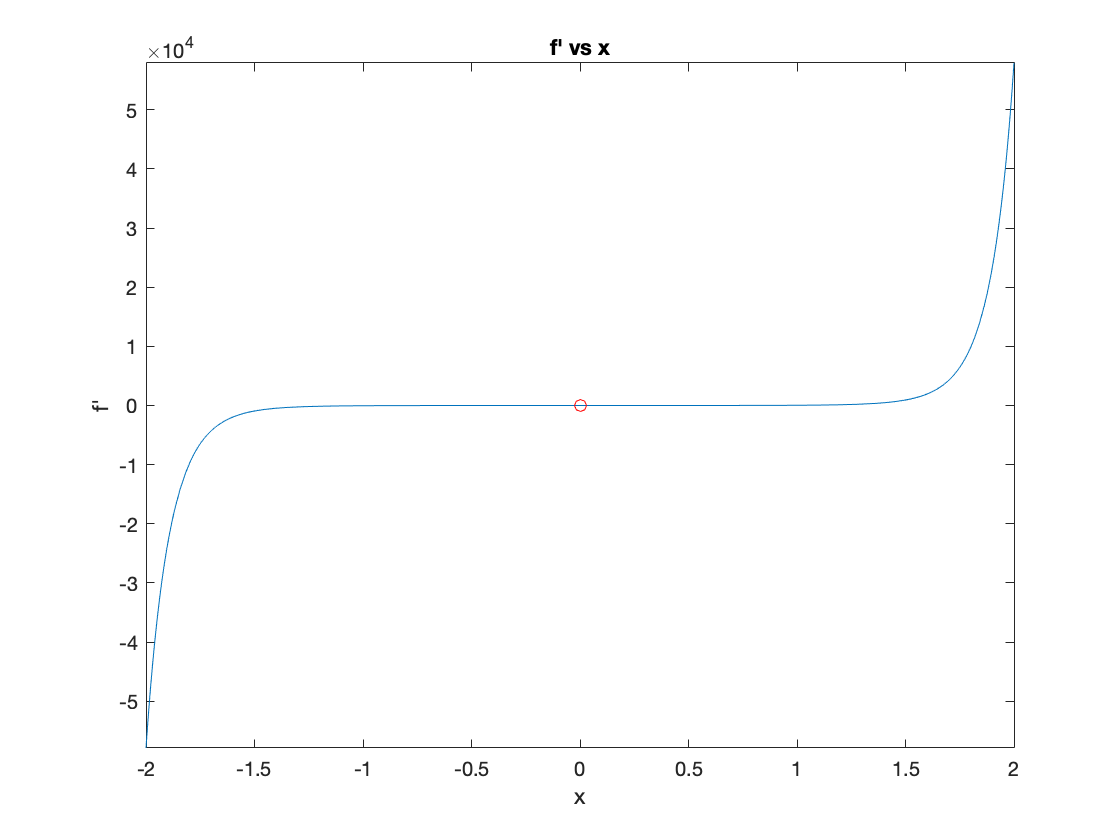

hold off        %hold back off